# **IO3xx Digital - I/O Functionality Switch**

This example demonstrates how to configure the Simulink model to switch between the implemented functionality and the digital input/output for a specific I/O line.

## Setup

### Prerequisites

You will require the following to run this example:

- A Speedgoat configuration file that supports **2 x DIO channel **and **1x PWM channel**

**    Note: **The example can easily be adapted to other code module functionalities and does not necessarily require the PWM functionality.

### Test Setup

This example does not require to have a hardware wiring in place. The example will not deploy an application to the target machine but demonstrates the configuration capabilities in the Simulink model.

## Initialize and Open the Simulink model

 
% Open Simulink model
modelName = 'sgMdl_IO3xx_Digital_FunctionalitySwitch';
open_system(modelName);

Before the Simulink model can be built, the I/O module and configuration file must be specified in the IO3xx Setup block, as this example can be executed on different configurable I/O modules. First, open the mask of the IO3xx Setup block and select your I/O module from the drop-down. Once the mask has extended, select the configuration file that supports the required functionalities.

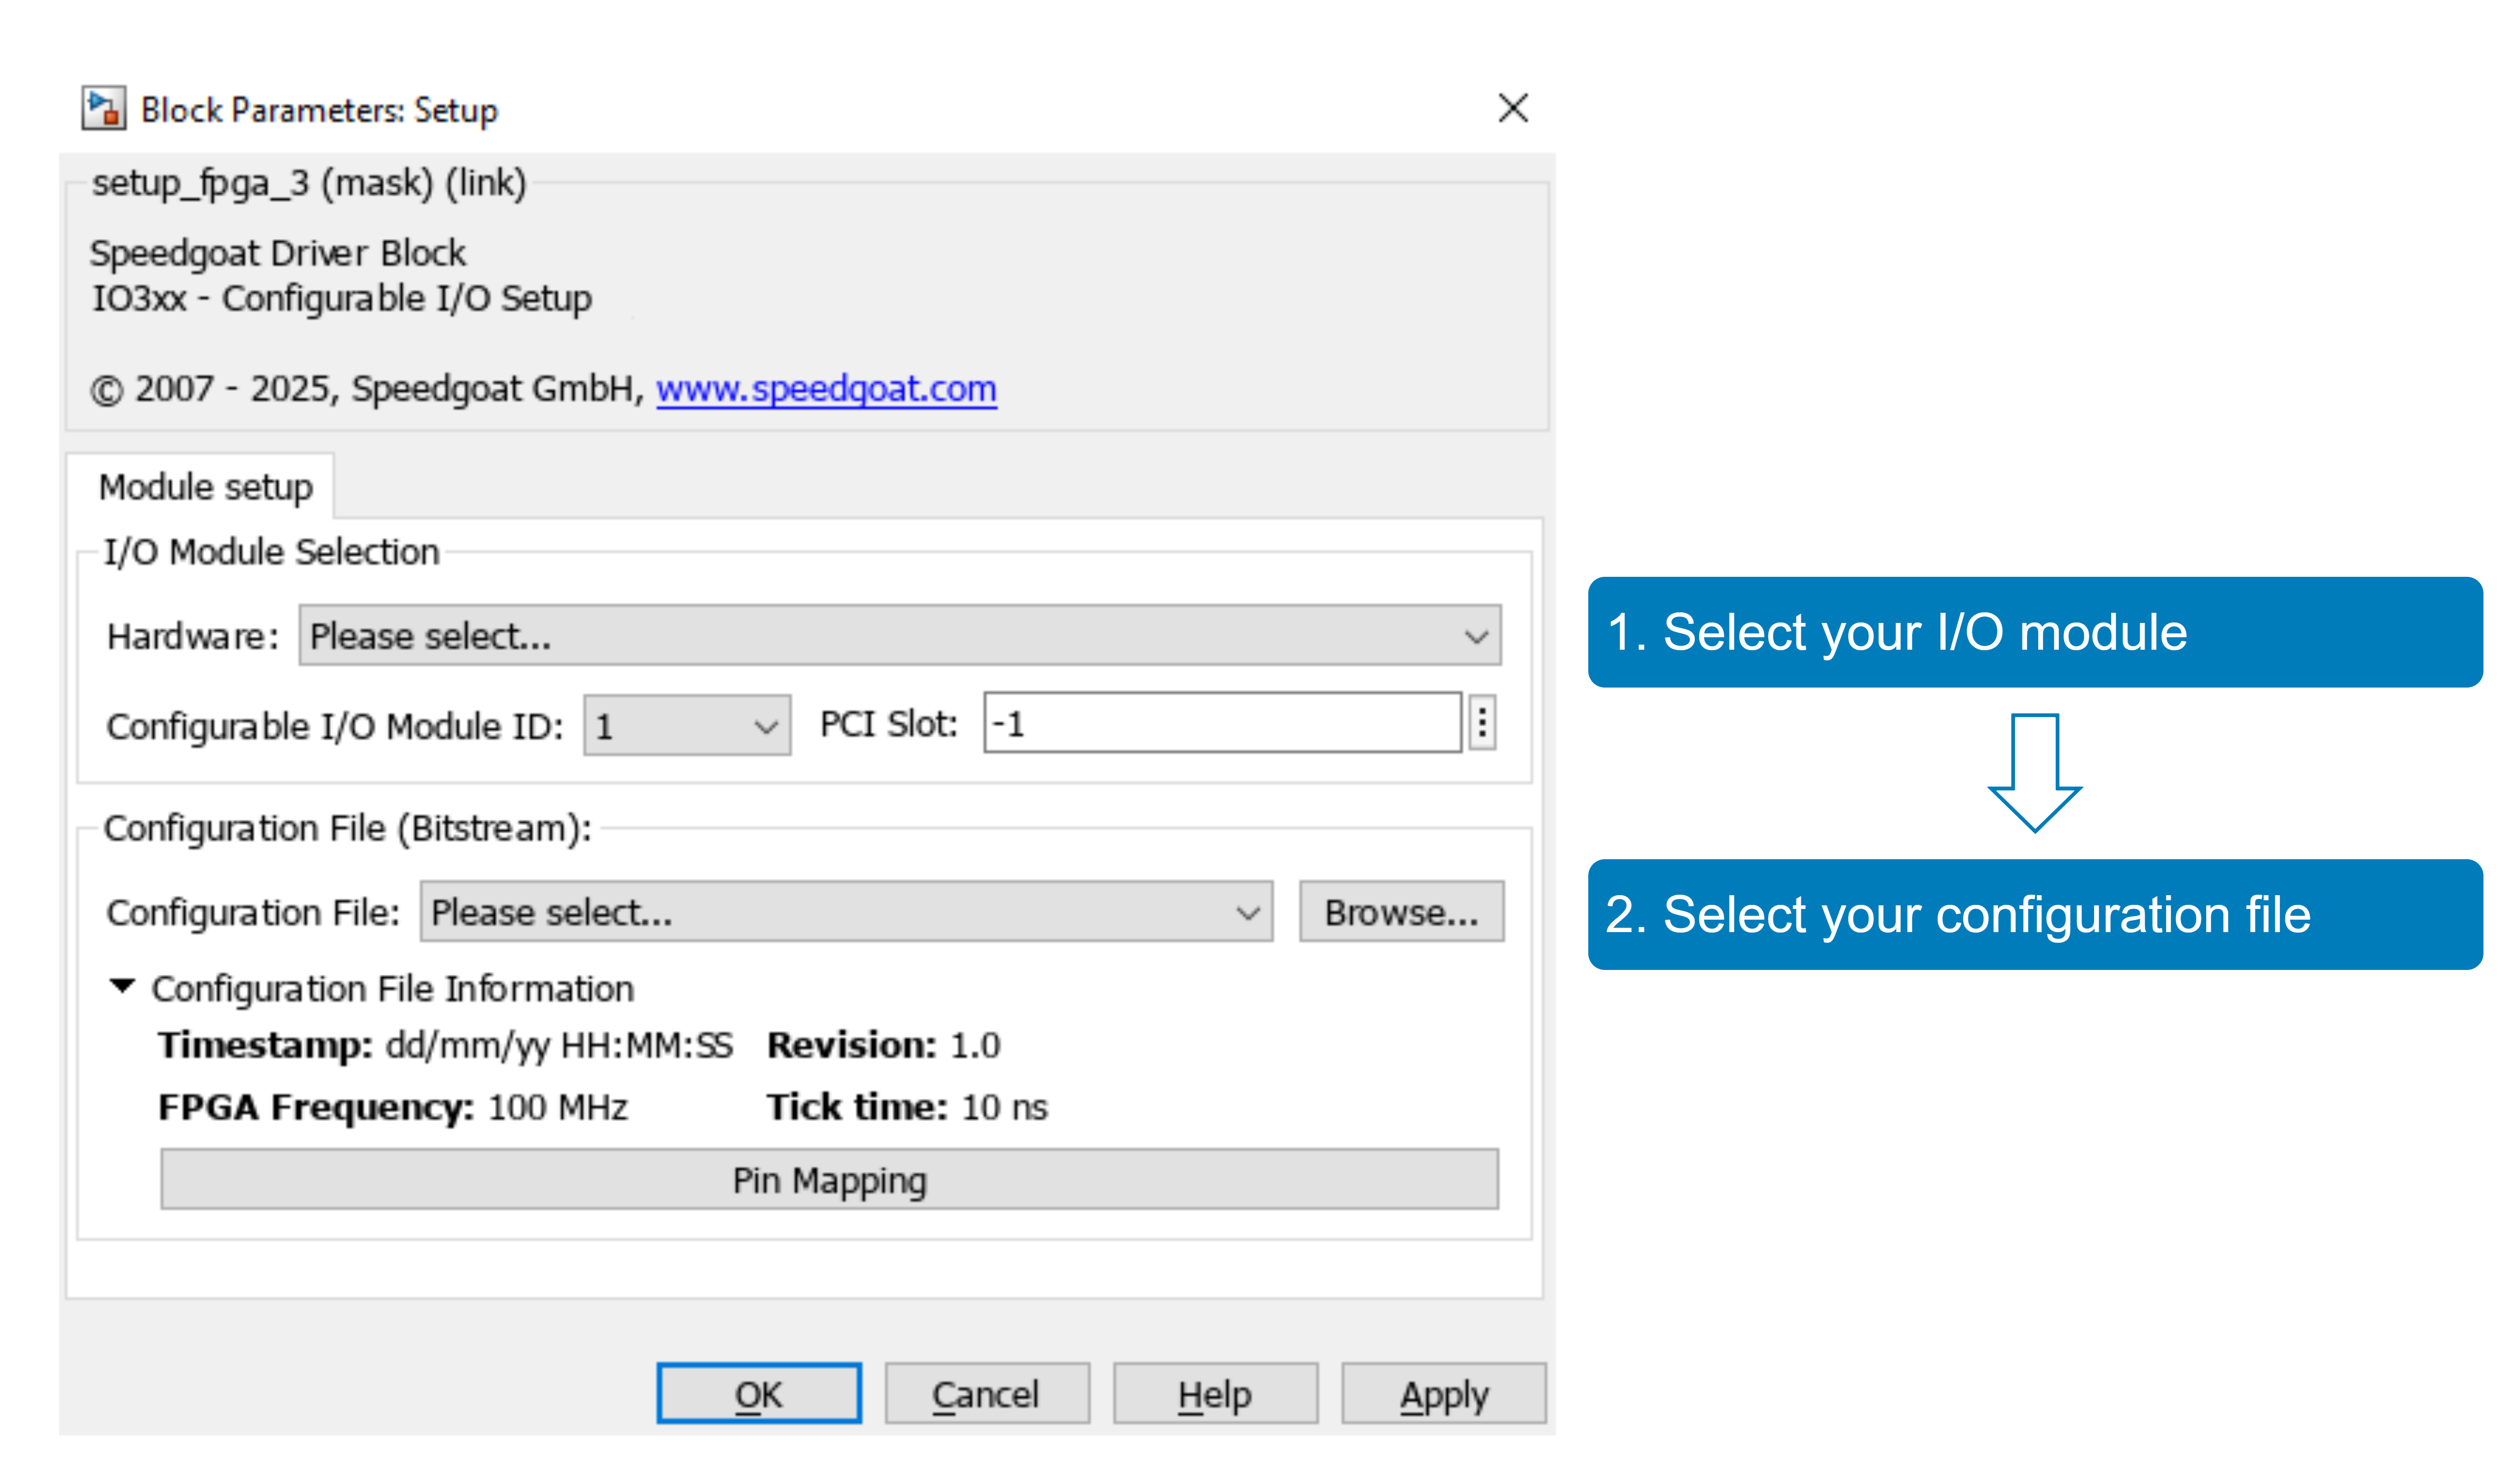

With the **Pin Mapping** button you can now check where the functionalities are located.

### Pin Mapping Information

This example uses the speedgoat_IO306_25k_RCP.mat configuration file from the IO306 Configuration Package. 

Once an I/O module and corresponding configuration file is selected, the button **Pin Mapping **will appear in the **Setup v3 **driver block mask, which allows the user to open a window illustrating the implemented functionality and the pin mapping for the configuration file.

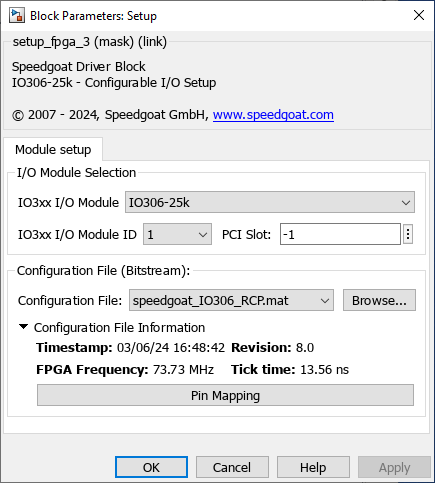   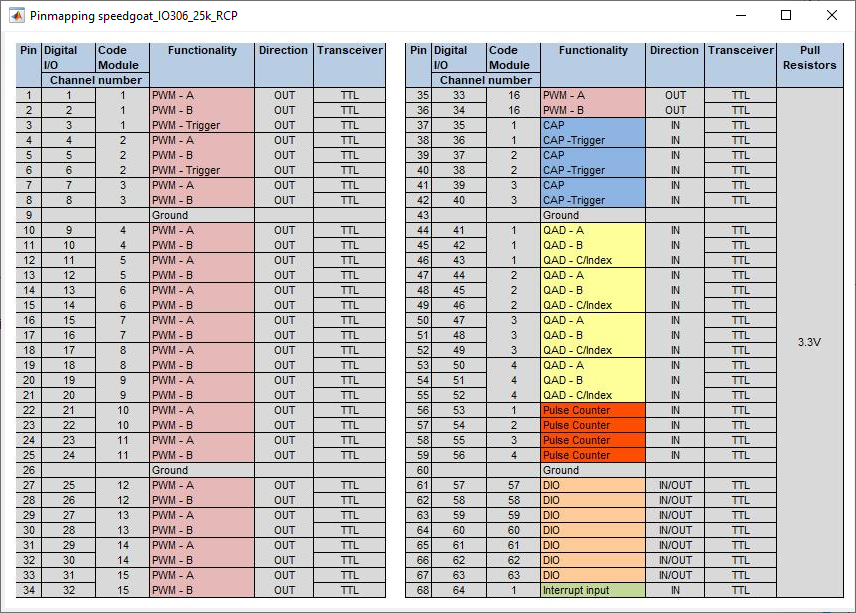

The pin mapping shows the implemented code module functionality (e.g. PWM, CAP, QAD, ...) and the corresponding mapping to the I/O pin or the external terminal board respectively. Configuration files, however, do not only support code module functionality but as well digital input/output (DIO) functionality on each physical I/O line. This is illustrated in the pin mapping with the following column descriptions:

- **Pin**: physical pin on the external terminal board

- **Digital I/O channel number**: channel number used to configure the Digital Input and Digital Output driver blocks

- **Code module channel number**: channel number used to configure the corresponding code module (e.g. PWM) driver blocks

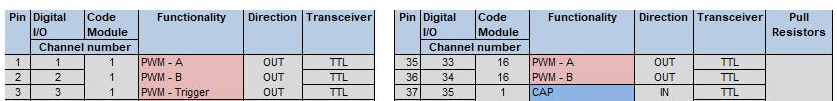

The two functionalities (digital I/O and code module) are mutually exclusive and can not be used at the same time, as they are using the same unique physical pin.

The configuration of which functionality is used is done in the Simulink model itself, by configuring the corresponding driver blocks. If the I/O should be used as digital input/output, configure the channel parameter of the **Digital Input v1** and **Digital Output v1 **driver blocks with the correct channel number and make sure the driver blocks using the same I/O pin (e.g. **PWM Generation v5**) has the corresponding channel number not configured. Vice versa if the PWM functionality is intended to be used, then make sure that the channel number of the digital input/output driver blocks are not configured.

In case a conflict occurs in the model due to a duplicate use of an I/O pin, an error message will be shown in the model Diagnostic Viewer indicating which Simulink driver blocks are affected. An example of the error message is given below.

### Configuration Mismatch

To illustrate the error that occurs if an I/O pin is used from multiple drivers, uncomment the **PWM Generation v5** driver block and update the Simulink model. **Note**: depending on the configuration file used, the configured channels on the driver blocks might need to be adapted so that a conflict on DIO and PWM functionality can be observed.

 
% Uncomment the PWM Generation v5 driver block
set_param([modelName,'/PWM generation'], 'chan','1');
set_param([modelName,'/PWM generation'],'Commented','off');
% Update the Simulink model and check for conflicts
set_param(modelName,'SimulationCommand','Update')

The error message indicates the conflict of the two DIO channels and PWM Generation channel 1, which use the same physical pins.

### Configuration for PWM Usage

To resolve the conflict, the **PWM Generation v5** driver block can be commented out again or a different channel can be used either on the **PWM Generation v5 **driver block, or as well on the **Digital Input v1** and **Digital Output v1 **output drivers.

Update the **PWM Generation v5** driver block to use channel 2 to resolve the issue:

 
% Use channel 2 of PWM instead of channel 1
set_param([modelName,'/PWM generation'],'chan','2');
% Update the Simulink model and check for conflicts
set_param(modelName,'SimulationCommand','Update')

## Additional References

- [IO306-25k Setup v3 driver block](https://www.speedgoat.com/help/slrt/page/io_main/refentry_fpga_setup_io306_25k)

- [Digital driver block documentation and examples](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_digital)